**Principio de Babinet**

Establecimiento de los parámetros físicos

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de la representación
Nx = 1024;
Ny = 1024;

% Condiciones de muestreo
dx =0.1*um;
dy =0.1*um;

% Longitud de Onda de iluminación
lambda = 650*nm;

Limite entre Espectro angular y trnasformada fresnel

zlim = Nx*dx^2/lambda

zlim = 1.5754e-05

% Ditancia Propagación
z = 1.5* zlim;

Diseño de los obstaculos y aberturas 

% Transmitancia
radioAberturaCirc = 20*um/dx; % Radio de 20um
aberturaCircular = filtroCircular ([Nx/2 Ny/2],radioAberturaCirc,[Ny Nx]);

radioObjeto = 10*um/dx; % Lado de 12um
objetoAnalisis = ~filtroCircular([Nx/2 Ny/2],radioObjeto,[Ny Nx]);


Se crean dos pantallas una con una abertura circular y el objeto como obstaculo en medio y otra pantalla con el objeto como abertura

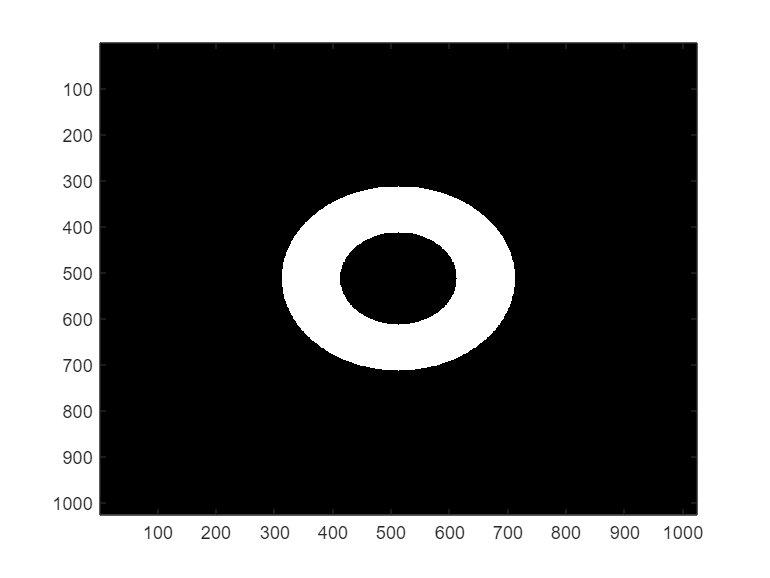

pantalla1 = (aberturaCircular & objetoAnalisis);
pantalla2 = ~objetoAnalisis;

imagesc(pantalla1)
colormap gray

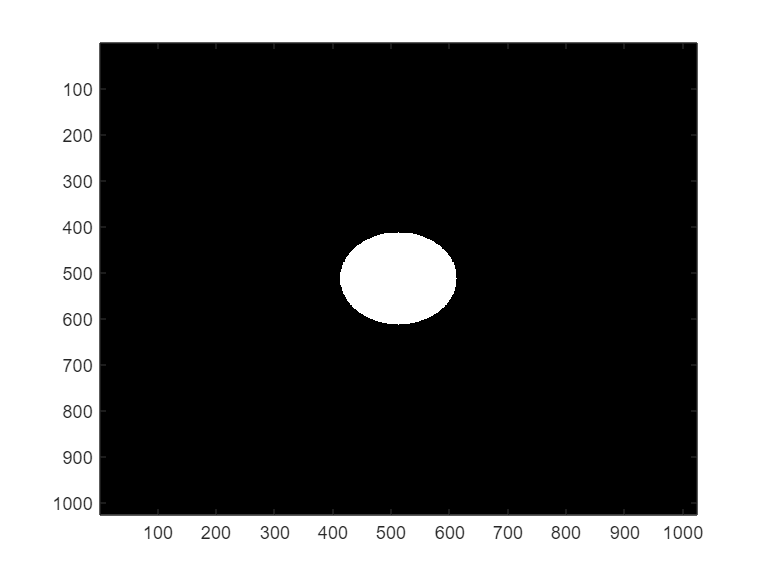

imagesc(pantalla2)
colormap gray

Se observa la propagación de luz atravesando la primera pantalla

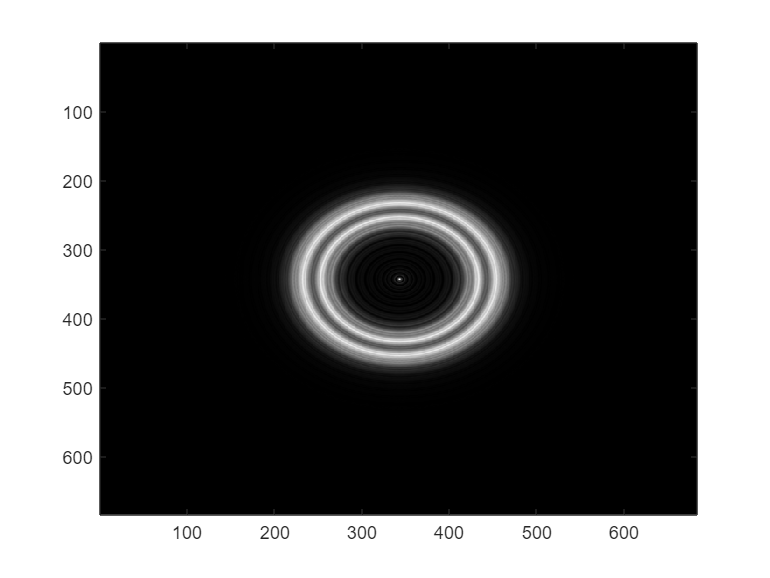

propagacionPantalla1 = transformadaFresnel(pantalla1,dx,dy,z,lambda,"dft",false,"zoom",true);
intensidad1 = abs(propagacionPantalla1).^2;
imagesc(intensidad1)

Se observa la propagación de luz atravesando la segunda pantalla

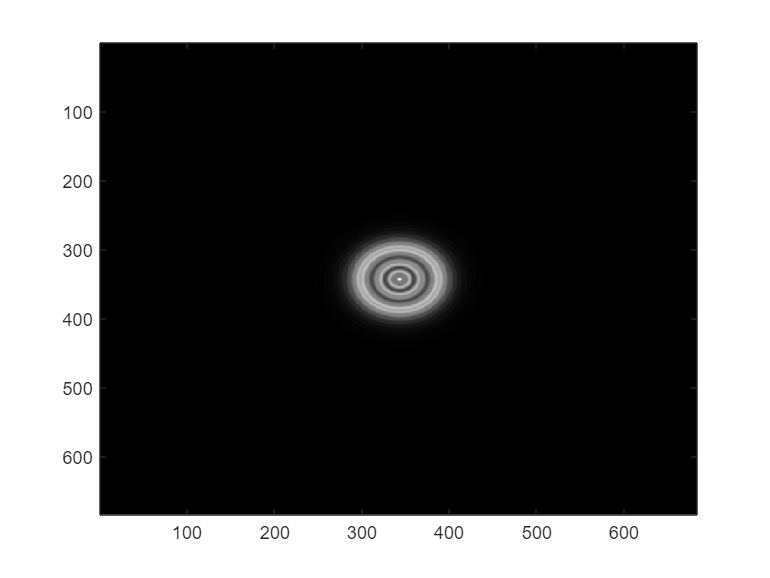

propagacionPantalla2 = transformadaFresnel(pantalla2,dx,dy,z,lambda,"dft",false,"zoom",true);
intensidad2 = abs(propagacionPantalla2).^2;
imagesc(intensidad2)

Ahora observamos la superposición de estas propagaciones en su dominio complejo

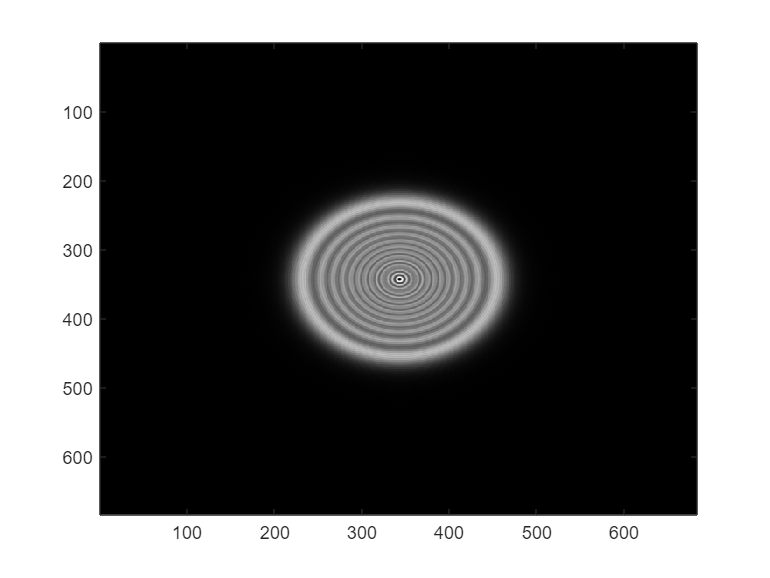

superPosicion = propagacionPantalla1+propagacionPantalla2;
imagesc(abs(superPosicion).^2)

Y se puede ver que las propagaciones de complementan ya que al superponerlas es igual que la propagacion de la abertura circular sin obstaculos, mostrando el principio de Babinet

aberturaCircularProp = transformadaFresnel(aberturaCircular,dx,dy,z,lambda,"dft",false,"zoom",true);
intensidadAbertura = abs(aberturaCircularProp).^2;
imagesc(intensidadAbertura)